% AAE 421 HW3 P1 MATLAB CODE 
% TOMOKI KOIKE
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
fdir = "C:\Users\Tomo\Desktop\studies\2020-Fall\AAE421\matlab\output\hw3"

fdir = "C:\Users\Tomo\Desktop\studies\2020-Fall\AAE421\matlab\output\hw3"

% Problem 1
% Setup initial conditions and input 
Vh_i = 0;
Vx_i = 51;  % ft/s
h_i  = 2000;  % ft
x_i  = 0;  % ft
CL   = 0.9;  % lift coefficient

simout = sim('simulink\hw3_p1_glider.slx')

simout =   Simulink.SimulationOutput:

                   tout: [526x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


% Problem 2
% (a)
% Control inputs 
dT = 0; dtheta = 0; da = 0; dr = 0;
u0 = 832;  % trim velocity ft/s
alpha_i = 0.1;  % initial alpha 0.1 rad
beta_i = 0;
h0 = 27000;  % trim altitude
sim_a = sim("hw3_p2_Boeing727.slx");

t = sim_a.simout.time;
long = sim_a.simout.signals.values;
lat  = sim_a.simout1.signals.values;
vert = sim_a.simout2.signals.values;

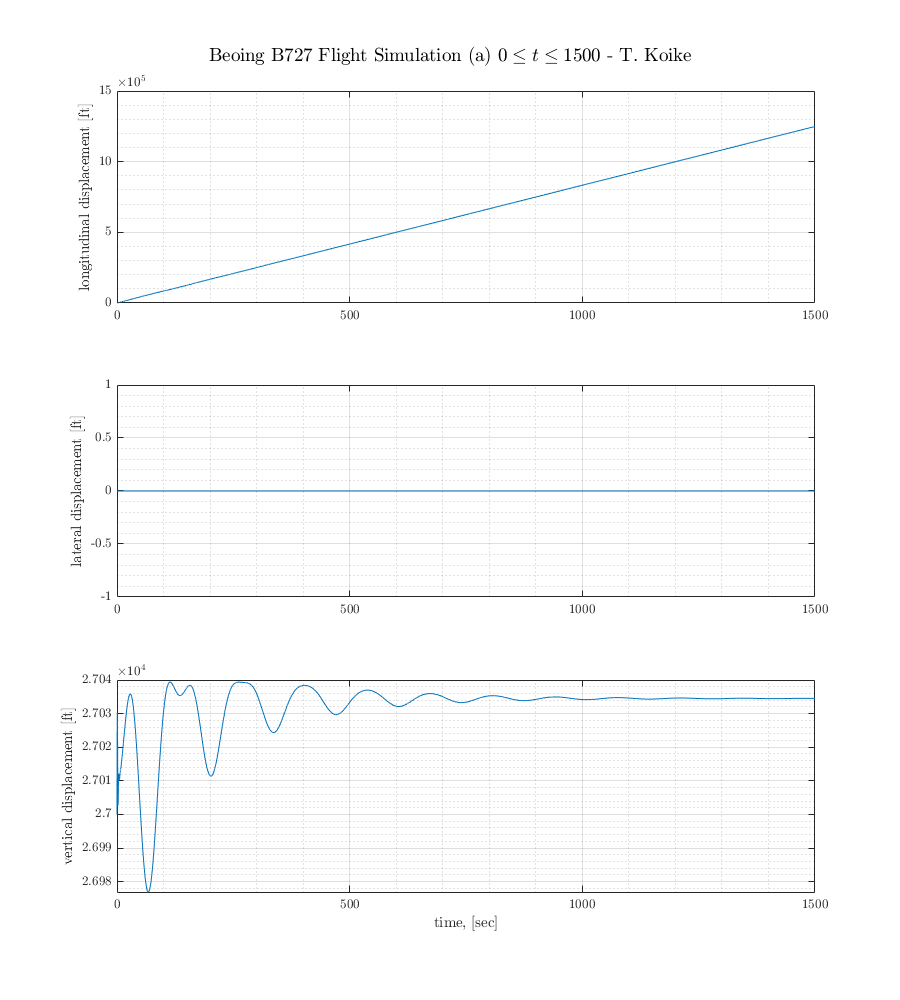

% Plotting 
fig1 = figure('Renderer',"painters", 'Position', [10 10 900 1000]);
subplot(3,1,1)
plot(t,long)
grid on; grid minor; box on;
ylabel('longitudinal displacement [ft]')
subplot(3,1,2)
plot(t,lat)
grid on; grid minor; box on;
ylabel('lateral displacement [ft]')
subplot(3,1,3)
plot(t,vert)
grid on; grid minor; box on;
ylabel('vertical displacement [ft]')
xlabel('time, [sec]')
sgtitle('Beoing B727 Flight Simulation (a) $0\leq t \leq 1500$ - T. Koike')
saveas(fig1, fullfile(fdir, "p2_a.png"))

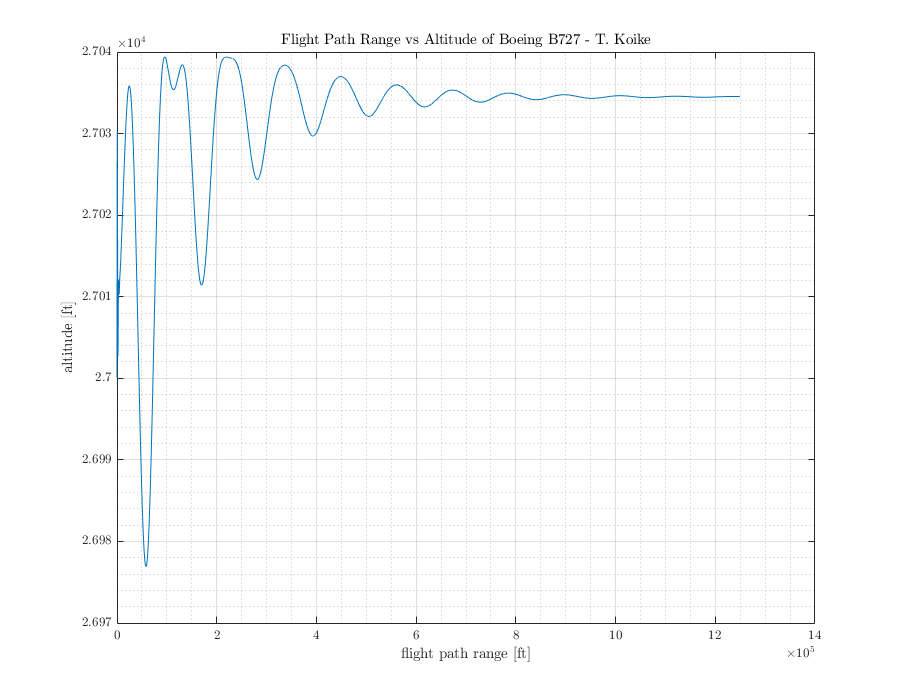


% range vs altitude 
fig2 = figure('Renderer',"painters", 'Position', [10 10 900 700]);
plot(long, vert)
grid on; grid minor; box on;
title('Flight Path Range vs Altitude of Boeing B727 - T. Koike')
xlabel('flight path range [ft]')
ylabel('altitude [ft]')
saveas(fig2, fullfile(fdir, "p2_a_rangeVSalt.png"))

% (b)
% Control inputs 
dT = 0; dtheta = 0; da = 0; dr = 0;
u0 = 832;  % trim velocity ft/s
alpha_i = 0;  % initial alpha 
beta_i = 0.1;  % initial beta 
h0 = 27000;  % trim altitude
sim_b = sim("hw3_p2_Boeing727.slx");

t = sim_b.simout.time;
long = sim_b.simout.signals.values;
lat  = sim_b.simout1.signals.values;
vert = sim_b.simout2.signals.values;

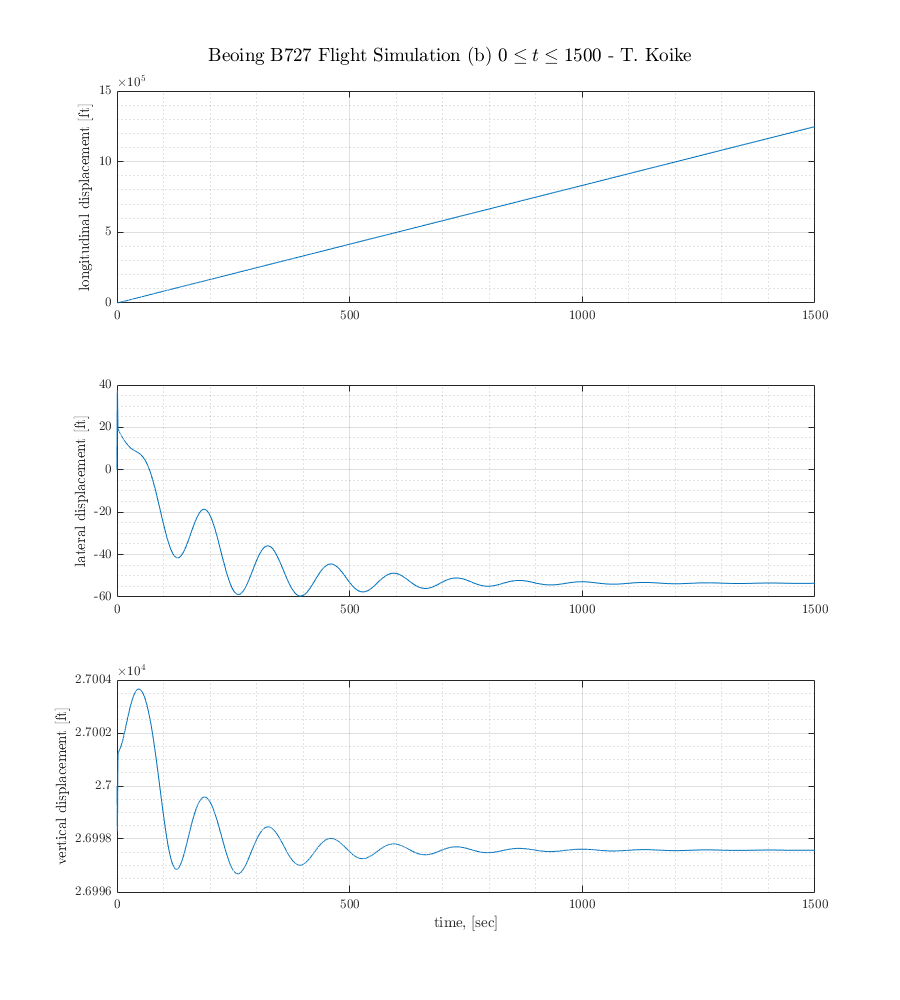

% Plotting 
fig1 = figure('Renderer',"painters", 'Position', [10 10 900 1000]);
subplot(3,1,1)
plot(t,long)
grid on; grid minor; box on;
ylabel('longitudinal displacement [ft]')
subplot(3,1,2)
plot(t,lat)
grid on; grid minor; box on;
ylabel('lateral displacement [ft]')
subplot(3,1,3)
plot(t,vert)
grid on; grid minor; box on;
ylabel('vertical displacement [ft]')
xlabel('time, [sec]')
sgtitle('Beoing B727 Flight Simulation (b) $0\leq t \leq 1500$ - T. Koike')
saveas(fig1, fullfile(fdir, "p2_b.png"))

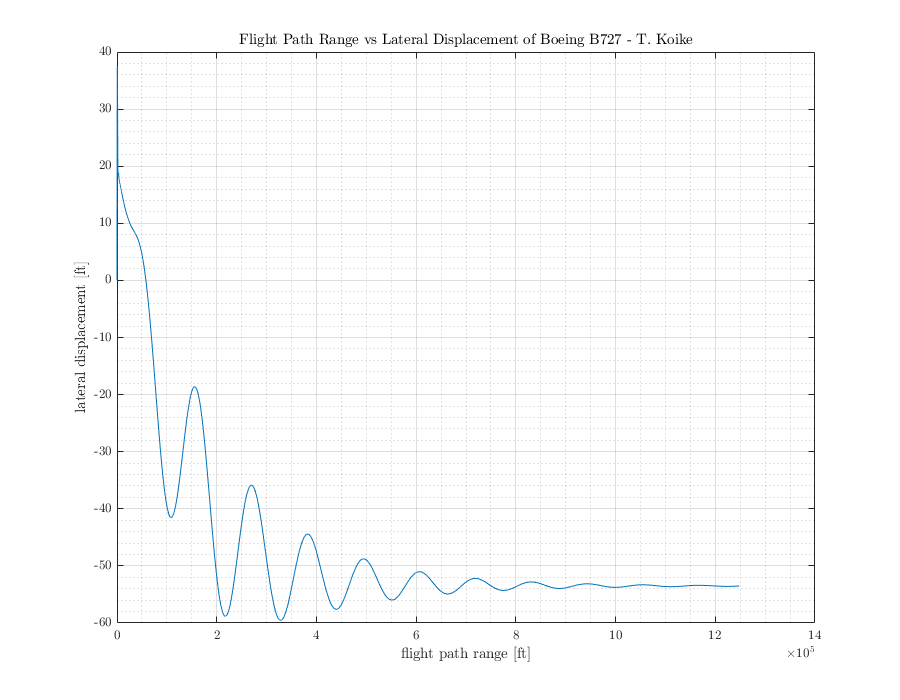


% range vs lateral displacement
fig2 = figure('Renderer',"painters", 'Position', [10 10 900 700]);
plot(long, lat)
grid on; grid minor; box on;
title('Flight Path Range vs Lateral Displacement of Boeing B727 - T. Koike')
xlabel('flight path range [ft]')
ylabel('lateral displacement [ft]')
saveas(fig2, fullfile(fdir, "p2_b_rangeVSlat.png"))

% Problem 3
